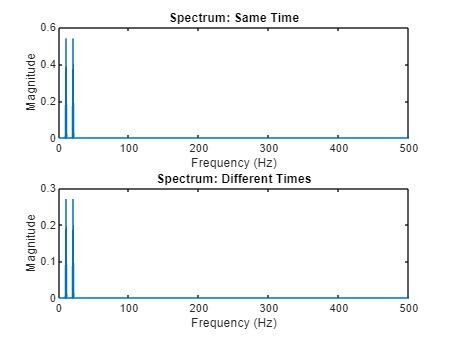

% Define parameters
Fs = 1000;          % Sampling frequency (Hz)
T = 2;              % Duration of signal (seconds)
t = 0:1/Fs:T-1/Fs;  % Time vector

% Define frequencies
f1 = 10;    % Frequency of first cosine wave (Hz)
f2 = 20;    % Frequency of second cosine wave (Hz)

% Generate signals
signal_same_time = cos(2*pi*f1*t) + cos(2*pi*f2*t);               % Two cosine waves occurring simultaneously
signal_different_times = [cos(2*pi*f1*t); cos(2*pi*f2*(t-1))];    % Same cosine waves occurring at different times

% Apply windowing
window = hamming(length(t));  % Hamming window
signal_same_time = signal_same_time .* window';
signal_different_times = signal_different_times .* repmat(window', 2, 1);

% Compute Fourier Transforms
N = length(signal_same_time);
frequencies = linspace(0, Fs/2, N/2);
spectrum_same_time = abs(fft(signal_same_time)/N);
spectrum_different_times = abs(fft(mean(signal_different_times, 1))/N);

% Plot spectra
subplot(2,1,1);
plot(frequencies, 2*abs(spectrum_same_time(1:N/2)));
title('Spectrum: Same Time');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
subplot(2,1,2);
plot(frequencies, 2*abs(spectrum_different_times(1:N/2)));
title('Spectrum: Different Times');
xlabel('Frequency (Hz)');
ylabel('Magnitude');